# IPV Assignment 4 (week 4) 

## **Initializations:**

addpath('/lib/dip/common/dipimage');  % Adds path to diplib
dip_initialise;  % Initilialize libraries
dipsetpref('imagefilepath','/home/amt/IPV/');  % Optional: sets default image saving/loading folder

## **Q2: Implement dilation and erosion in MATLAB**

Morphology is a technique to process ojects in an binary or greyscale image with a structuring element based on the characteristics of its shape.

The structuring element is positioned in all possible locations in the image and it is compared to all neighbours withing its size. The result on each opeation can lead for the SE to 'Fit' when all SE elements are on the object, 'Hit' when at least one element of the SE is on the object or 'Miss' when all elements of the SE are not on the object 

The most basic operators for binary morphology are:

- Erosion. The effect of this operator is for the foreground pixels tho shrink in size.

- Dilation. The opposite of Erosion, the foreground pixels grow in size.

- Opening. Similar to Erosion but definitely less destructive, this results on removing small object.

- Closing. As expected similar to Dilation but opposite to Opening, this effect results on filling small gaps in objects.

Here we will experimenting the results of the Erosion and Dilation operators.

I = imread('Untitled.tif');

SESQ = strel('square', 32);
SELV = strel('line', 32, 90);
SELH = strel('line', 32, 0);
SESP = strel('disk', 32);
SELD = strel('line', 32, 45);

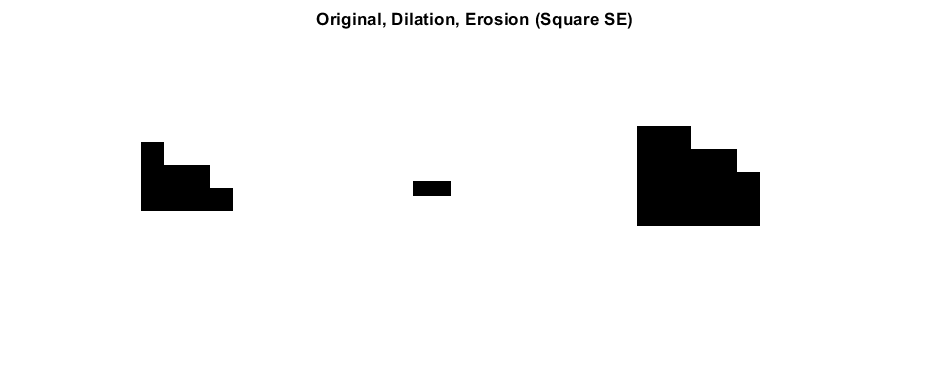

JDSESQ = imdilate(I, SESQ);
JESESQ = imerode(I, SESQ);

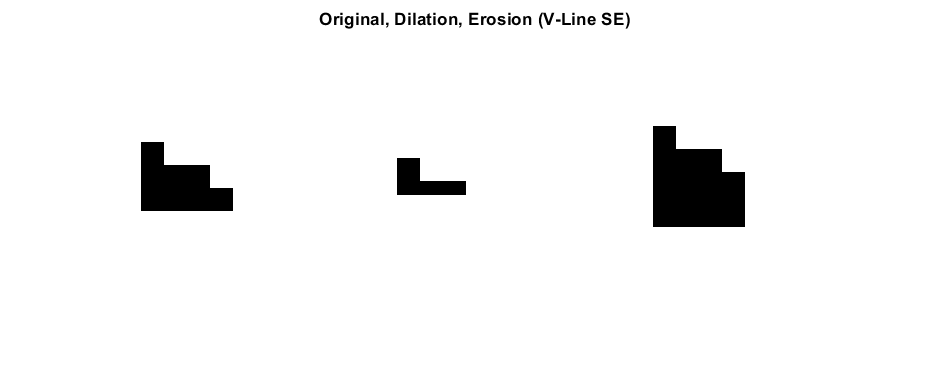

imshow([I, JDSESQ, JESESQ]), title('Original, Dilation, Erosion (Square SE)')
JDSELV = imdilate(I, SELV);
JESELV = imerode(I, SELV);

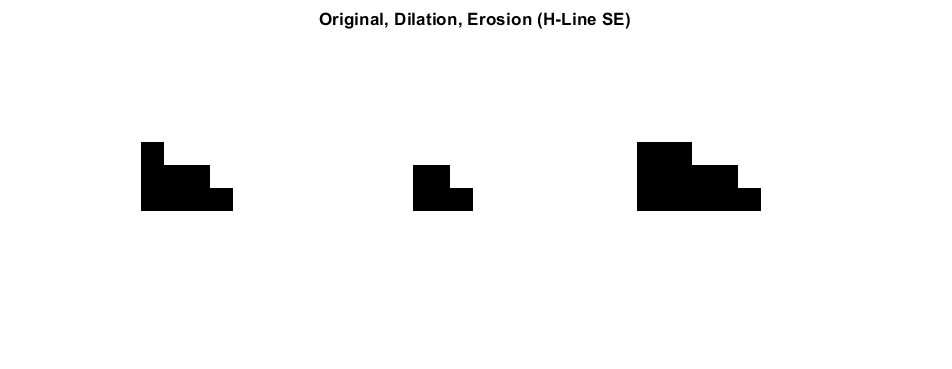

imshow([I, JDSELV, JESELV]), title('Original, Dilation, Erosion (V-Line SE)')
JDSELH = imdilate(I, SELH);
JESELH = imerode(I, SELH);

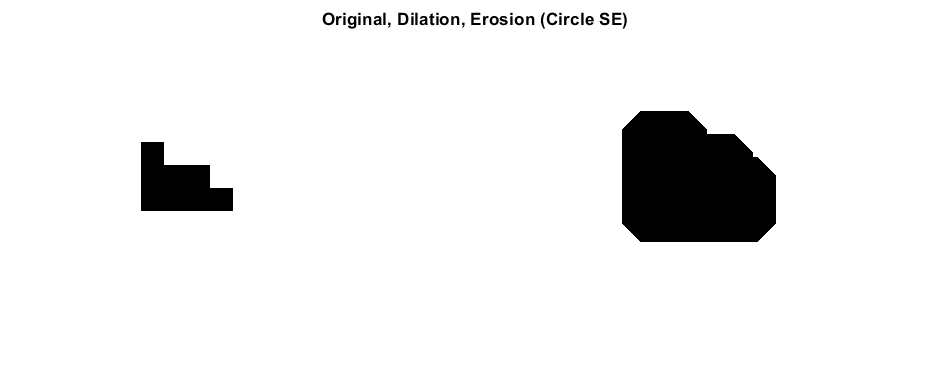

imshow([I, JDSELH, JESELH]), title('Original, Dilation, Erosion (H-Line SE)')
JDSESP = imdilate(I, SESP);
JESESP = imerode(I, SESP);

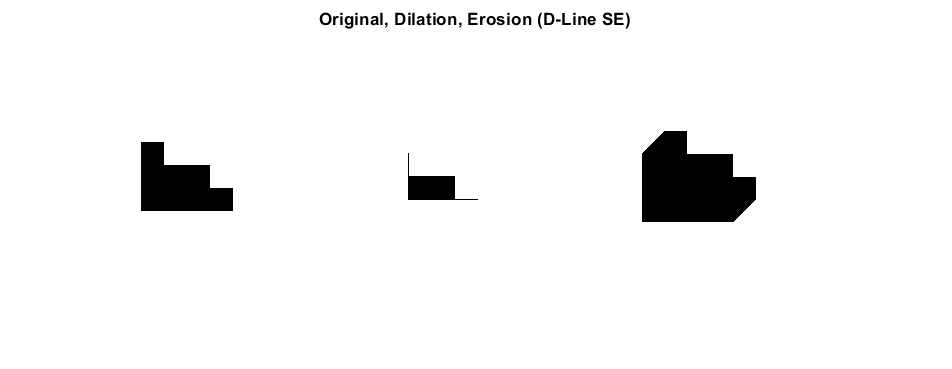

imshow([I, JDSESP, JESESP]), title('Original, Dilation, Erosion (Circle SE)')
JDSELD = imdilate(I, SELD);
JESELD = imerode(I, SELD);

imshow([I, JDSELD, JESELD]), title('Original, Dilation, Erosion (D-Line SE)')

**Note:**

Since in MATLAB the 'object' or foreground in the image is the white and the black is the background we get the same result as the assignment but reversed. In addition, the image used on the assignment is 8x8 while the image used here is 256x256.

## **Q2: Finish Part 7: Binary Morphology**

## **Q3: Write down all the commands used in Q2B**

## **Q4: Goal: Make your onw demo for binary morphology**

## **Q5: Edge detection**

We are going to use the Sobel Operator to emphasize the edge of the image. This operator works as a discrete differentiation operator, since it calculates the gradient in a point on a discrete-sampled function. 

To do it, we will use two convolution matrix to calculate the gradient vector in every point in the x and y axis. These matrixes are:

x =[1 0 -1;
    2 0 -2;
    1 0 -1]

x =      1     0    -1
     2     0    -2
     1     0    -1


y =[1 2 1;
    0 0 0;
    -1 -2 -1]

y =      1     2     1
     0     0     0
    -1    -2    -1


Being G the result of the Sobel filter, we are going to computate the next operation:


$$\sqrt{{\mathrm{Gx}}^2 +{\mathrm{Gy}}^2 }$$


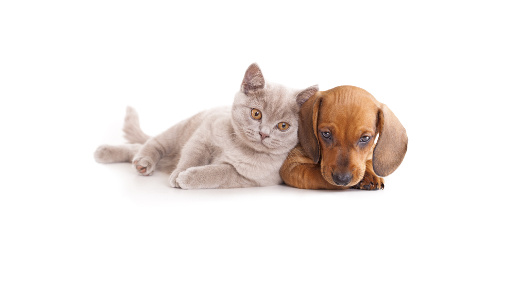

I = imread('/mnt/63B5E4A911AE9F06/0_GitHub/ImageProcessingVision/Week4/puppy_and_kitten.jpg');
imshow(I);

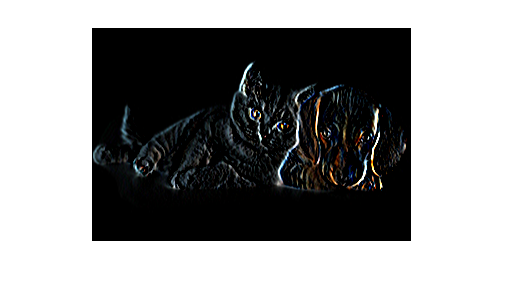

Gx = imfilter(I, x);
imshow(Gx);

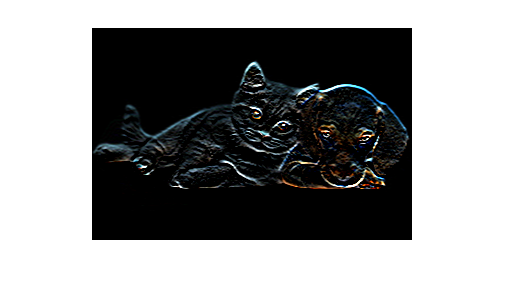

Gy = imfilter(I, y);
imshow(Gy);


G = Gx.^2 + Gy.^2

Undefined function 'realsqrt' for input arguments of type 'uint8'.

for i 1:size(G,1)
    for j 1:size(G,2)
        G(i, j) = sqrt(G(i, j))
    end
end
imshow(G);

## **Q6: Use morphological operations to implement in MATLAB**